% OPTI 512L
% LAB 12
% Mohanbabu Mani


% Function

function result = TrapInt(F, a, b, N)
    h = (b - a) / N;
    result = (F(a) + F(b)) / 2;

    for i = 1:(N-1)
        x = a + i * h;          
        result = result + F(x);   
    end

    result = result * h;
    
end

% 1.

F = inline('sin(x)');

a = 0;          
b = pi;          
N = 100;         

integral_approx = TrapInt(F, a, b, N);

fprintf('Integration bounds: [%f, %f]\n', a, b);

Integration bounds: [0.000000, 3.141593]


fprintf('Approximate integral: %.10f\n', integral_approx);

Approximate integral: 1.9998355039



fprintf('N\t\tIntegral Approximation\n');

N		Integral Approximation


N_values = [10, 50, 100, 500, 1000, 5000];

for N = N_values
    result = TrapInt(F, a, b, N);
    fprintf('%d\t\t%.10f\n', N, result);
end

10		1.9835235375
50		1.9993419831
100		1.9998355039
500		1.9999934203
1000		1.9999983551
5000		1.9999999342




functions = {
    inline('sin(x)');      
    inline('x^2');         
    inline('exp(x)');      
    inline('1/(1+x^2)')   
};

bounds = [
    0, pi;       
    0, 1;       
    0, 1;        
    0, 1       
];

for i = 1:length(functions)
    F = functions{i};
    a = bounds(i, 1);
    b = bounds(i, 2);
    result = TrapInt(F, a, b, 1000);
    fprintf('Function %d: Integral = %.10f\n', i, result);
end

Function 1: Integral = 1.9999983551
Function 2: Integral = 0.3333335000
Function 3: Integral = 1.7182819716
Function 4: Integral = 0.7853981217


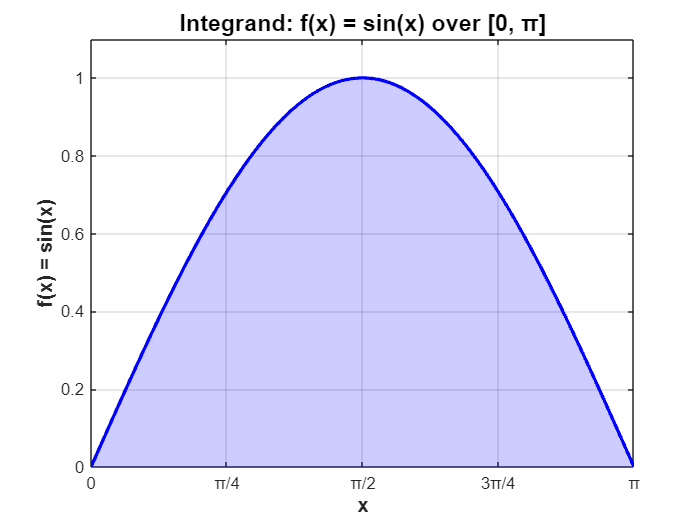

% 2.


a = 0;             
b = pi;             
N = 100;           
exact_value = 2;   

x_plot = linspace(a, b, 1000);
y_plot = sin(x_plot);

figure('Name', 'Integrand Visualization', 'NumberTitle', 'off');
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
grid on;
hold on;
fill(x_plot, y_plot, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('f(x) = sin(x)', 'FontSize', 12, 'FontWeight', 'bold');
title('Integrand: f(x) = sin(x) over [0, π]', 'FontSize', 14, 'FontWeight', 'bold');
xlim([a, b]);
ylim([0, 1.1]);
set(gca, 'XTick', 0:pi/4:pi);
set(gca, 'XTickLabel', {'0', 'π/4', 'π/2', '3π/4', 'π'});


F = @(x) sin(x);
fprintf(' Panel width (h): %f\n\n', (b-a)/N);

 Panel width (h): 0.031416




approx_value = TrapInt(F, a, b, N);

fprintf('Approximate integral (N = %d):  %.10f\n', N, approx_value);

Approximate integral (N = 100):  1.9998355039


fprintf('Exact integral value: %.10f\n', exact_value);

Exact integral value: 2.0000000000


fprintf('Absolute error: %.10e\n', abs(approx_value - exact_value));

Absolute error: 1.6449611256e-04


fprintf('Relative error: %.6f %%\n\n', abs(approx_value - exact_value)/exact_value * 100);

Relative error: 0.008225 %




fprintf('%-10s %-18s %-15s %-15s\n', 'N', 'Approximation', 'Abs Error', 'Rel Error (%)');

N          Approximation      Abs Error       Rel Error (%)  


N_values = [10, 20, 50, 100, 200, 500, 1000];
errors = zeros(size(N_values));

for i = 1:length(N_values)
    n = N_values(i);
    result = TrapInt(F, a, b, n);
    abs_error = abs(result - exact_value);
    rel_error = abs_error / exact_value * 100;
    
    fprintf('%-10d %-18.10f %-15.8e %-15.6f\n', n, result, abs_error, rel_error);
    errors(i) = abs_error;
end

10         1.9835235375       1.64764625e-02  0.823823       
20         1.9958859727       4.11402729e-03  0.205701       
50         1.9993419831       6.58016924e-04  0.032901       
100        1.9998355039       1.64496113e-04  0.008225       
200        1.9999588765       4.11235208e-05  0.002056       
500        1.9999934203       6.57974060e-06  0.000329       
1000       1.9999983551       1.64493434e-06  0.000082       



fprintf('\n');

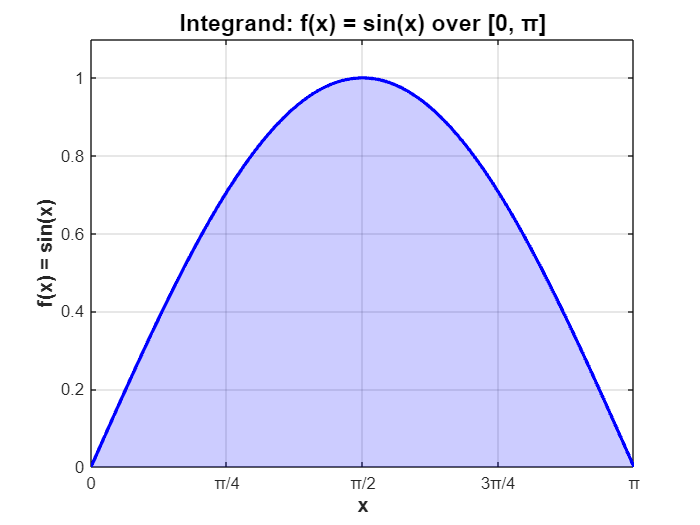

% 3.

a = 0;             
b = pi;             
Tol = 1e-6;         
exact_value = 2;   

x_plot = linspace(a, b, 1000);
y_plot = sin(x_plot);

figure('Name', 'Integrand Visualization', 'NumberTitle', 'off');
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
grid on;
hold on;
fill(x_plot, y_plot, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('x', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('f(x) = sin(x)', 'FontSize', 12, 'FontWeight', 'bold');
title('Integrand: f(x) = sin(x) over [0, π]', 'FontSize', 14, 'FontWeight', 'bold');
xlim([a, b]);
ylim([0, 1.1]);
set(gca, 'XTick', 0:pi/4:pi);
set(gca, 'XTickLabel', {'0', 'π/4', 'π/2', '3π/4', 'π'});


F = @(x) sin(x);
N = 4;                 
I_prev = 0;             
iteration = 0;
max_iterations = 20;   
iteration_data = [];   

fprintf('%-12s %-12s %-18s %-18s %-15s %-15s\n', ...
    'Iteration', 'N (Panels)', 'Integral (I)', 'I_prev', '|I - I_prev|', 'Frac. Accuracy');

Iteration    N (Panels)   Integral (I)       I_prev             |I - I_prev|    Frac. Accuracy 



while iteration < max_iterations
    iteration = iteration + 1;
    I = TrapInt(F, a, b, N);

    if iteration == 1
        frac_accuracy = abs(I); 
        convergence_check = frac_accuracy;  
    else
        frac_accuracy = abs(I - I_prev) / abs(I_prev);
        convergence_check = abs(I - I_prev);
    end

    iteration_data = [iteration_data; iteration, N, I, I_prev, abs(I - I_prev), frac_accuracy];

    fprintf('%d%-11s %d%-11s %2.10g%-6s %2.10g%-6s %2.8e%-7s %2.8e\n', ...
        iteration, '', N, '', I, '', I_prev, '', abs(I - I_prev), '', frac_accuracy);
 
    if iteration > 1 && convergence_check < Tol * abs(I_prev)
       
        fprintf('|I - I_prev| < Tol|I_prev|\n');
        fprintf('  %.8e < %.8e\n', convergence_check, Tol * abs(I_prev));
        break;
    end

    I_prev = I;
    N = N * 2;
end

1            4            1.896118898        0       1.89611890e+00        1.89611890e+00
2            8            1.974231602       1.896118898       7.81127040e-02        4.11961001e-02
3            16            1.993570344       1.974231602       1.93387418e-02        9.79557910e-03
4            32            1.998393361       1.993570344       4.82301720e-03        2.41928619e-03
5            64            1.999598389       1.998393361       1.20502767e-03        6.02998235e-04
6            128            1.9998996       1.999598389       3.01211544e-04        1.50636021e-04
7            256            1.9999749       1.9998996       7.53000508e-05        3.76519155e-05
8            512            1.999993725       1.9999749       1.88248355e-05        9.41253589e-06
9            1024            1.999998431       1.999993725       4.70619781e-06        2.35310629e-06
10            2048            1.999999608       1.999998431       1.17654875e-06        5.88274839e-07


|I - I_prev| < Tol|I_prev|


  1.17654875e-06 < 1.99999843e-06



fprintf('Number of iterations: %d\n', iteration);

Number of iterations: 10


fprintf('Final number of panels: %d\n', N/2);  

Final number of panels: 1024


fprintf('Final integral value: %.15g\n', I_prev);

Final integral value: 1.99999843126838



fprintf('N must be at least %d panels\n\n', N/2);

N must be at least 1024 panels





iterations = iteration_data(:, 1);
N_values = iteration_data(:, 2);
I_values = iteration_data(:, 3);
errors = iteration_data(:, 5);
frac_errors = iteration_data(:, 6);


fprintf('Iter  N      Integral          |I-I_prev|      Frac. Accuracy\n');

Iter  N      Integral          |I-I_prev|      Frac. Accuracy


for i = 1:size(iteration_data, 1)
    fprintf('%2.0f    %5.0f  %.14g   %2.8e   %2.8e\n', ...
        iteration_data(i, 1), iteration_data(i, 2), iteration_data(i, 3), ...
        iteration_data(i, 5), iteration_data(i, 6));
end

 1        4  1.896118897937   1.89611890e+00   1.89611890e+00
 2        8  1.9742316019456   7.81127040e-02   4.11961001e-02
 3       16  1.9935703437723   1.93387418e-02   9.79557910e-03
 4       32  1.9983933609701   4.82301720e-03   2.41928619e-03
 5       64  1.99959838864   1.20502767e-03   6.02998235e-04
 6      128  1.9998996001842   3.01211544e-04   1.50636021e-04
 7      256  1.9999749002351   7.53000508e-05   3.76519155e-05
 8      512  1.9999937250706   1.88248355e-05   9.41253589e-06
 9     1024  1.9999984312684   4.70619781e-06   2.35310629e-06
10     2048  1.9999996078171   1.17654875e-06   5.88274839e-07


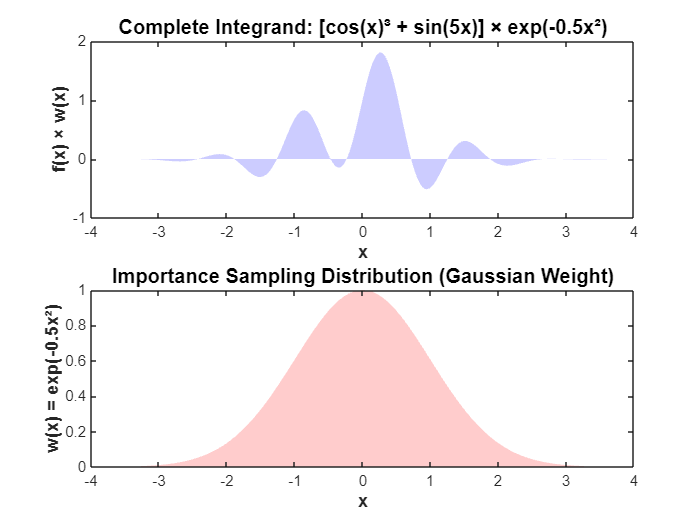

% 4.



a = -4;           
b = 4;              
N_samples = 100000; 
g = @(x) cos(x).^3 + sin(5*x);  
w = @(x) exp(-0.5*x.^2);         
integrand = @(x) g(x) .* w(x);  

x_plot = linspace(a, b, 1000);
y_plot = integrand(x_plot);
w_plot = w(x_plot);

figure('Name', 'Integrand Visualization', 'NumberTitle', 'off');
subplot(2, 1, 1);
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
grid on;
fill(x_plot, y_plot, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('x', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('f(x) × w(x)', 'FontSize', 11, 'FontWeight', 'bold');
title('Complete Integrand: [cos(x)³ + sin(5x)] × exp(-0.5x²)', 'FontSize', 12, 'FontWeight', 'bold');
xlim([a, b]);

subplot(2, 1, 2);
plot(x_plot, w_plot, 'r-', 'LineWidth', 2);
grid on;
fill(x_plot, w_plot, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('x', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('w(x) = exp(-0.5x²)', 'FontSize', 11, 'FontWeight', 'bold');
title('Importance Sampling Distribution (Gaussian Weight)', 'FontSize', 12, 'FontWeight', 'bold');
xlim([a, b]);


mu = 0;           
sigma = 1;      

X_samples = mu + sigma * randn(N_samples, 1);
f_samples = cos(X_samples).^3 + sin(5*X_samples);
w_samples = exp(-0.5 * X_samples.^2);
p_samples = (1 / (sigma * sqrt(2*pi))) * exp(-(X_samples - mu).^2 / (2*sigma^2));

weighted_samples = f_samples .* w_samples ./ p_samples;
integral_estimate = mean(weighted_samples);
std_error = std(weighted_samples) / sqrt(N_samples);
confidence_interval = 1.96 * std_error; 

fprintf('Number of samples: %d\n', N_samples);

Number of samples: 100000


fprintf('Integral estimate: %.10g\n', integral_estimate);

Integral estimate: 1.142820704


fprintf('Standard error:    %.10e\n', std_error);

Standard error:    6.4833407017e-03



N_test_values = [100, 500, 1000, 5000, 10000, 50000, 100000, 500000];
estimates = zeros(size(N_test_values));
std_errors_array = zeros(size(N_test_values));

fprintf('%-12s %-18s %-18s\n', 'N Samples', 'Estimate', 'Std Error');

N Samples    Estimate           Std Error         



for i = 1:length(N_test_values)
    N_test = N_test_values(i);
    X_test = mu + sigma * randn(N_test, 1);
    f_test = cos(X_test).^3 + sin(5*X_test);
    w_test = exp(-0.5 * X_test.^2);
    p_test = (1 / (sigma * sqrt(2*pi))) * exp(-(X_test - mu).^2 / (2*sigma^2));
    
    weighted_test = f_test .* w_test ./ p_test;
    est = mean(weighted_test);
    err = std(weighted_test) / sqrt(N_test);
    
    estimates(i) = est;
    std_errors_array(i) = err;
    
    fprintf('%-12d %-18.10g %-18.10e\n', N_test, est, err);
end

100          1.090256184        2.0960340625e-01  
500          1.203086213        9.2716371041e-02  
1000         1.225087697        6.3357169376e-02  
5000         1.171690021        2.8866317637e-02  
10000        1.147962409        2.0532079298e-02  
50000        1.141084535        9.1413943672e-03  
100000       1.143046355        6.4670935977e-03  
500000       1.151235357        2.8916290231e-03  


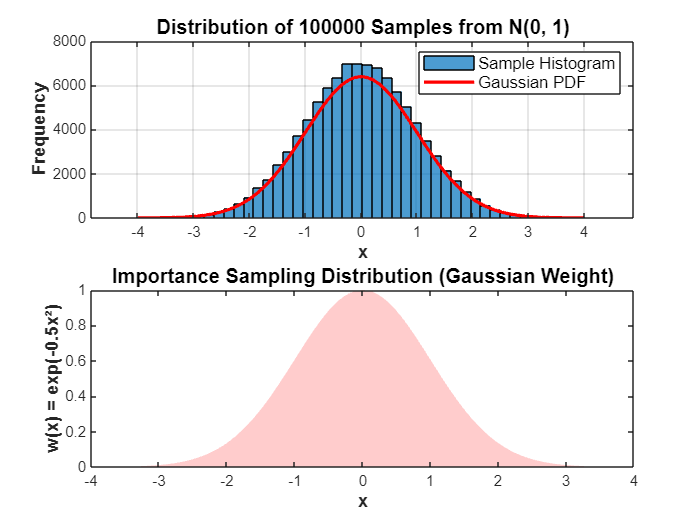


subplot(2, 1, 1);
histogram(X_samples, 50, 'FaceAlpha', 0.7, 'EdgeColor', 'black');
hold on;
x_range = linspace(-4, 4, 1000);
p_range = (1 / (sigma * sqrt(2*pi))) * exp(-(x_range - mu).^2 / (2*sigma^2));
p_range_scaled = p_range * length(X_samples) * (8/50);
plot(x_range, p_range_scaled, 'r-', 'LineWidth', 2);
xlabel('x', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Frequency', 'FontSize', 11, 'FontWeight', 'bold');
title(sprintf('Distribution of %d Samples from N(0, 1)', N_samples), 'FontSize', 12, 'FontWeight', 'bold');
legend('Sample Histogram', 'Gaussian PDF', 'FontSize', 10);
grid on;

% 5.


g = @(x) cos(x).^3 + sin(5*x); 
w = @(x) exp(-0.5*x.^2);        
integrand = @(x) g(x) .* w(x);  
a = -4;
b = 4;
I_true = integral(integrand, a, b, 'AbsTol', 1e-12);
target_tolerance = 1e-3; 
fprintf('%.1e\n\n', target_tolerance);

1.0e-03




N_trap = 10;  
max_N_trap = 1e6;
trap_evals = NaN;
trap_error = NaN;

while N_trap <= max_N_trap
   
    I_trap = TrapInt(integrand, a, b, N_trap);
    
    error = abs(I_trap - I_true);
    
    if error < target_tolerance
        trap_evals = N_trap + 1; 
        trap_error = error;
        break;
    end
    
    N_trap = N_trap + 10; 
end

if ~isnan(trap_evals)
    
    fprintf('%d\n', trap_evals);
    fprintf('  Error: %.2e\n', trap_error);
else
    fprintf('Failed in %d.\n', max_N_trap);
end

11


  Error: 5.79e-05



mu = 0;
sigma = 1;
N_mc = 100; 
max_N_mc = 1e6;
mc_evals = NaN;
mc_error = NaN;
mc_std_error = NaN;
num_trials = 50; 

while N_mc <= max_N_mc
    trial_errors = zeros(num_trials, 1);
    
    for k = 1:num_trials
        X = mu + sigma * randn(N_mc, 1);
        f_vals = cos(X).^3 + sin(5*X);
        w_vals = exp(-0.5 * X.^2);
        p_vals = (1 / (sigma * sqrt(2*pi))) * exp(-(X - mu).^2 / (2*sigma^2));
        estimates = f_vals .* w_vals ./ p_vals;
        I_mc = mean(estimates);
        trial_errors(k) = abs(I_mc - I_true);
    end
    
    avg_abs_error = mean(trial_errors);
    
    if avg_abs_error < target_tolerance
        mc_evals = N_mc;
        mc_error = avg_abs_error;
        break;
    end
    
    N_mc = round(N_mc * 1.2); 
end

if ~isnan(mc_evals)
    
    fprintf('Avg Error: %.2e\n', mc_error);
else
    fprintf('Failed at %d\n', max_N_mc);
end

Failed at 1000000



if ~isnan(trap_evals) && ~isnan(mc_evals)
    ratio = mc_evals / trap_evals;
    fprintf('Ratio (MC / Trapezoidal): %.2f\n', ratio);
    
    if trap_evals < mc_evals
        fprintf('%.1fx more efficient.\n', ratio);
    else
        fprintf('%.1fx more efficient.\n', 1/ratio);
    end
end